addpath('Classes')  
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# FSFB Controller with PID Action - Tuning

This script attempts to optimize the response of the linear moving setpoint controller with PID augmented state vector. The script will attempt to get a viable setpoint tracking response that keeps $\beta$ under $25^{\circ}$ and the torque actuation under 73 mNm. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 


%Choose a plant model symbolic variable to create a matlab function block from

% plant_model = Lnrzed_EOMs.Lin_EOMs; %Choose the linear decoupled model of the plant.
plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated



FSFB_PID = Lin_FSFB_Cntrl(Lnrzed_EOMs, plant_model, VDefs, 'FSFB PID Controller')

LMSPC_PID =   Lin_Mvng_Stpt_Cntr_SS with properties:

               VDefs: [1×1 Var_Defs]
         Lnrzed_EOMs: [1×1 Lnrzed_EOMs]
            sys_mats: [1×1 struct]
        sim_response: []
           ctrl_type: 'FSFB PID Controller'
         stateVec_1a: [5×1 sym]
     stateVec_1a_dot: [5×1 sym]
         stateVec_2a: [5×1 sym]
     stateVec_2a_dot: [5×1 sym]
       x_setpointVec: [3×1 sym]
       y_setpointVec: [3×1 sym]
     sim_file_string: 'Simulink_Models/Simulation/FSFB_PID_Sim'
     HIL_file_string: []
    ctrl_file_string: 'Simulink Models/Models to Reference/FSFB_PID_Controller'
               plant: [8×1 sym]
             x_s_vec: []
             y_s_vec: []
                u_FF: []


## Desired Trajectory in x and y

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide

%Rose curve specified by k
tot_period = 10 %this many seconds before the entire rose curve loops around

tot_period = 10

n = 2; %Selects a rose curve
d = 1; %Selects a rose curve
k = n/d; 
omega_sim = omega_rose(tot_period,n,d)

omega_sim = 0.6283

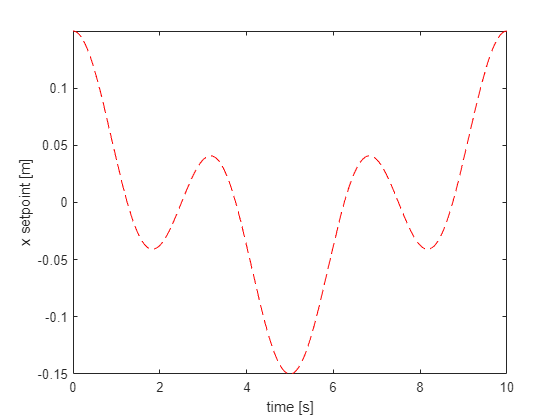

des_traj_sym_x(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
des_traj_sym_y(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

figure
fplot(des_traj_sym_x, 'r--') 
xlim([0 tot_period]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

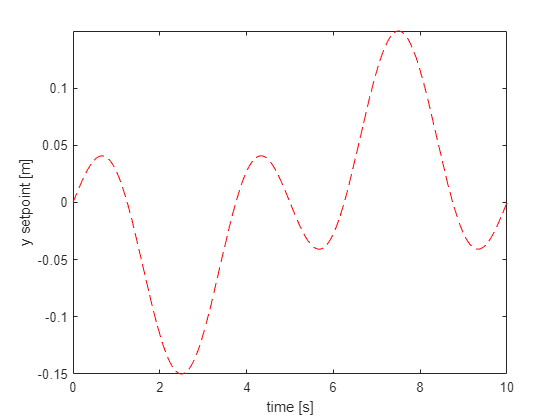


figure
fplot(des_traj_sym_y, 'r--') 
xlim([0 tot_period]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

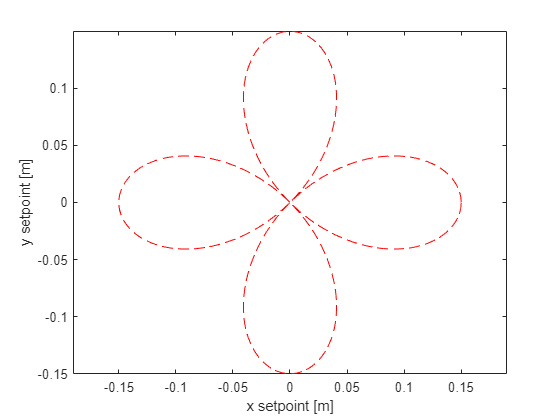


tplot = 0:0.01:tot_period;
setpoint_shape = double([des_traj_sym_x(tplot)',des_traj_sym_y(tplot)']);
figure
plot(setpoint_shape(:,1),setpoint_shape(:,2), 'r--')
xlabel('x setpoint [m]')
ylabel('y setpoint [m]')
axis equal

## K Matrices for the Decoupled Systems


A1a = FSFB_PID.sys_mats.A1a;
A2a = FSFB_PID.sys_mats.A2a;

B1a = FSFB_PID.sys_mats.B1a;
B2a = FSFB_PID.sys_mats.B2a;

% K_PID1 = place(double(A1a),double(B1a), [-10 -20 -30 -4 -5]);
% K_PID2 = place(double(A2a),double(B2a), [-10 -20 -30 -4 -5]);

%THESE WORKED WELL ENOUGH FOR r = 0.1, freq = 1/3
Q_e_ix = 1/15^2;
Q_e_x = 1/.001^2;
Q_e_xd = 1/.002^2; 
Q_b = 1/deg2rad(40)^2/.5; %5
Q_bd = 1/omega_sim^2/3;

Q = [Q_e_ix 0 0 0 0; 
     0 Q_e_x 0 0 0;
     0 0 Q_e_xd 0 0;
     0 0 0 Q_b 0;
     0 0 0 0 Q_bd];

R = 1/(73/1000)^2/2; 

% Q_e_ix = .5;
% Q_e_x = 2;
% Q_e_xd = 15; 
% Q_b = 1/deg2rad(45)^2/5; 
% Q_bd = 1/omega_sim^2/5;
% 
% Q = [Q_e_ix 0 0 0 0; 
%      0 Q_e_x 0 0 0;
%      0 0 Q_e_xd 0 0;
%      0 0 0 Q_b 0;
%      0 0 0 0 Q_bd];
% 
% R = 1/(73/1000)^2*20; 

K_PID1 = lqr(double(A1a), double(B1a), Q,R)

K_PID1 =    -0.0069 -105.4736  -77.4982  116.8547   13.9853


K_PID2 = lqr(double(A2a), double(B2a), Q,R)

K_PID2 =     0.0069  105.4736   77.4982  116.8547   13.9853


% K_PID2(2) = 2.5*K_PID2(2)
% K_PID2(3) = 1.15*K_PID2(3)

## Simulate Responses

%Specify simulation time
tspan = [0 3*tot_period];

%Specify initial conditions
x_0 = [0; 0; 0; 0; 0; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

%Time constant for first order smoothing
Tau = 2;

FSFB_PID.Run_Sim(des_traj_sym_x,des_traj_sym_y, tspan, x_0, Tau, K_PID1, K_PID2);

Error using sym/matlabFunctionBlock>getBlock
A new block named 'Simulink Models/Models to Reference/Simulated_Plant/Plant_Function' cannot be added

Error in sym/matlabFunctionBlock (line 65)
b = getBlock(block);

Error in Lin_Mvng_Stpt_Cntr_SS/Run_Sim (


simout_PID = FSFB_PID.sim_response;

% %Plot the PID controller results
PID_fig = FSFB_PID.plot_results('FSFB w/ PID action');

Animate Responses

t_window = tot_period;
i_plot = simout_PID.tout>=2*tot_period & simout_PID.tout<=3*tot_period;
Animate_Response(simout_PID.x(i_plot,1),simout_PID.x_s_vec(i_plot,1),simout_PID.x(i_plot,5),simout_PID.y_s_vec(i_plot,1),simout_PID.tout(i_plot),30,'LMSP_PID.gif', r_sim, t_window)

view_vec = [140 40];
Animate_Response_3D(simout_PID.x(i_plot,:),simout_PID.tout(i_plot),25,'LMSP_PID_3D.gif',VDefs, view_vec, setpoint_shape)